#### Test file for labeling automation algorithm

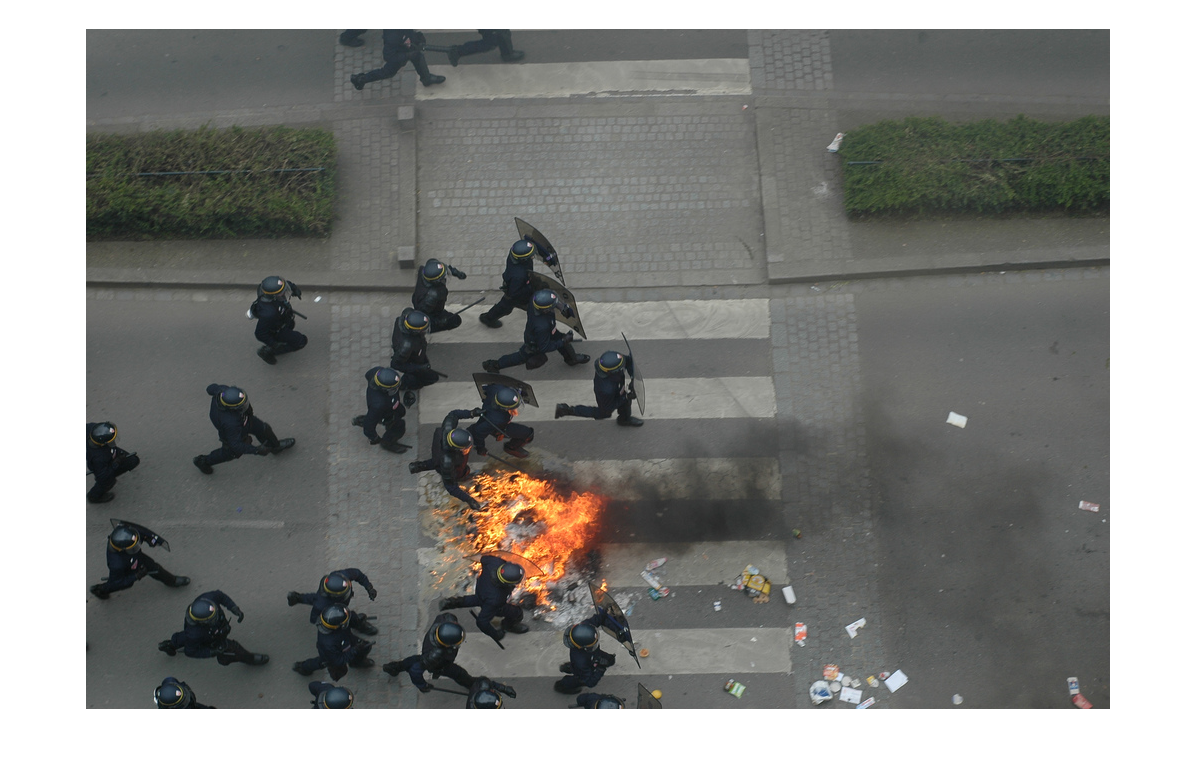

I = imread('123371157.jpg');
imshow(I)

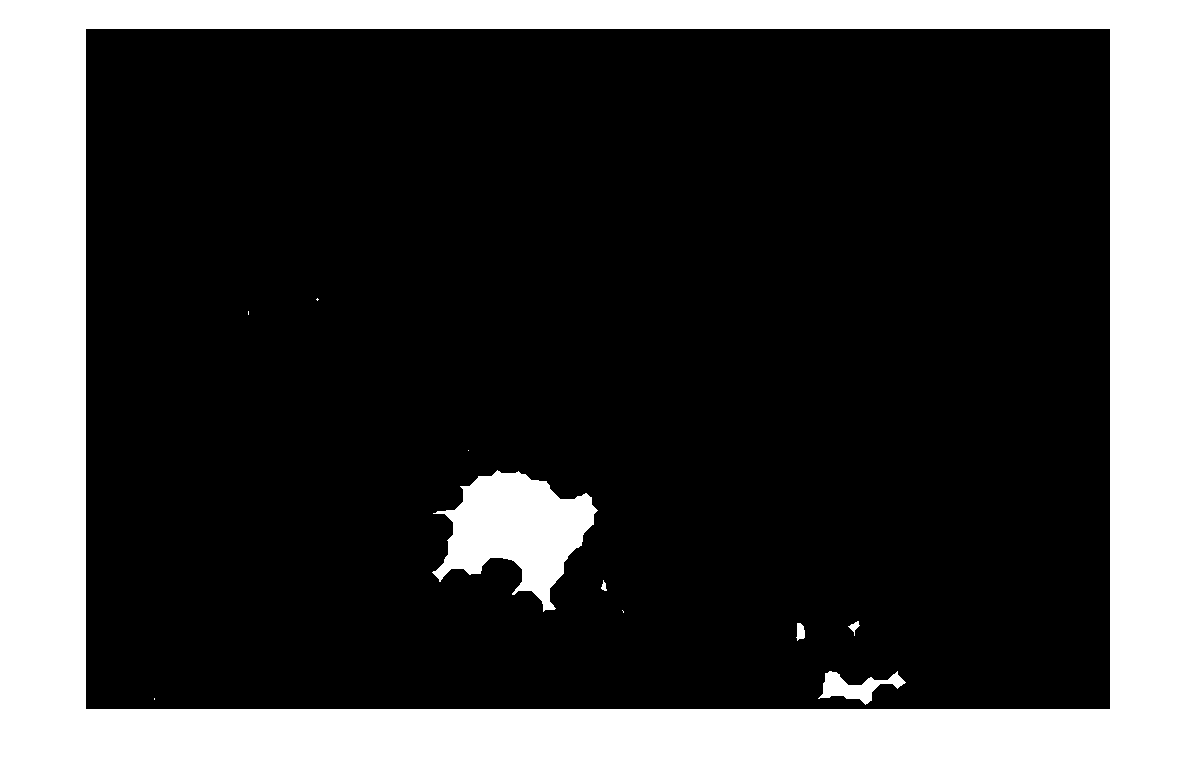

[BW,maskedRGBImage] = extract_red(I);
BW_C = imclose(BW, strel('disk', 15));
BW_f = imfill(BW_C, 'holes');
imshow(BW_f)

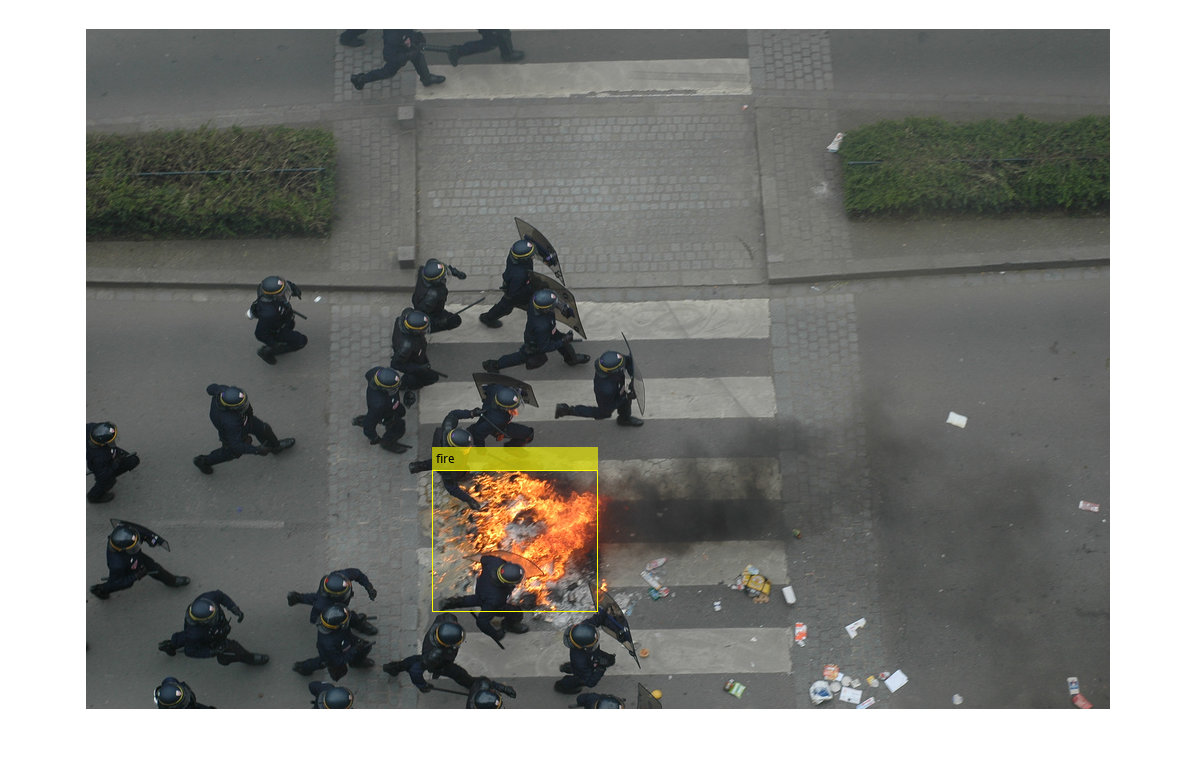

s = regionprops(BW_f);
maxVals = arrayfun(@(struct)max(struct.Area(:)),s);
[~, i] = max(maxVals);
f = insertObjectAnnotation(I, 'rectangle', s(i).BoundingBox, 'fire');
imshow(f)

*Copyright 2019 The MathWorks, Inc.*